# Tait Modified Equation Of State (EOS) DISCONTINUOUS Fitting

## **Specific Volume v(T, P) data:**

*Find the coefficients of Tait EOS that fit the following curves for **Polystyrene (PS)**:*

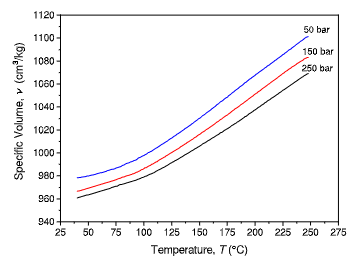

*Variation of the specific volume with temperature and pressure (Kattinger et al., 2021).*

**Data sampling above Glass Temperature (MELT):**

%curva 1: 50 bar
TD1_melt = 273.15+[94.693 105.359 114.999 135.097 150.273 189.848 199.281 226.145 241.525 246.857];

rho1_melt = [994.760 1000.927 1006.895 1020.224 1030.369 1060.210 1067.172 1086.071 1097.609 1100.792];

PD1_melt = [50 50 50 50 50 50 50 50 50 50];

%curva 2: 150 bar
TD2_melt = 273.15+[95.329 103.944 114.406 153.170 171.217 195.825 211.615 229.251 239.710 247.505];

rho2_melt = [983.421 988.195 993.765 1018.035 1030.369 1047.876 1059.414 1072.146 1078.909 1083.286];

PD2_melt = [150 150 150 150 150 150 150 150 150 150];

%curva 3: 250 bar
TD3_melt = 273.15+[107.037 130.011 149.702 176.776 184.000 195.439 218.203 239.327 247.120];

rho3_melt = [981.431 993.964 1005.502 1022.014 1026.653 1034.547 1049.666 1063.79 1068.963];

PD3_melt = [250 250 250 250 250 250 250 250 250];

Each of the variables is concatenated into a single array

TD_melt=[TD1_melt TD2_melt TD3_melt];
PD_melt=[PD1_melt PD2_melt PD3_melt].*100000;
rho_melt=[rho1_melt rho2_melt rho3_melt].*1e-06;

**Data sampling below Glass Temperature (SOLID):**

%curva 1: 50 bar
TD1_solid = 273.15+[40.250 56.320 66.377 75.611 82.177];

rho1_solid = [978.211 981.033 983.819 987.002 989.588];

PD1_solid = [50 50 50 50 50];

%curva 2: 150 bar
TD2_solid = 273.15+[40.125 48.335 59.212 69.678 80.555];

rho2_solid = [966.511 968.700 971.684 974.668 978.248];

PD2_solid = [150 150 150 150 150];

%curva 3: 250 bar
TD3_solid = 273.15+[40.137 45.677 53.476 61.685 72.151 87.748];

rho3_solid = [960.145 962.135 964.323 966.511 969.893 974.469];

PD3_solid = [250 250 250 250 250 250];

Each of the variables is concatenated into a single array

TD_solid=[TD1_solid TD2_solid TD3_solid];
PD_solid=[PD1_solid PD2_solid PD3_solid].*100000;
rho_solid=[rho1_solid rho2_solid rho3_solid].*1e-06;

## **Tait Modified EOS:**

The equations of the Tait model are summarized below:

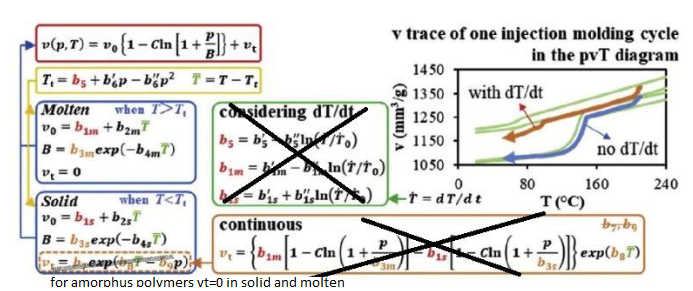

*2 Domain Tait EOS PVT model equations (Wang et al., 2019).*

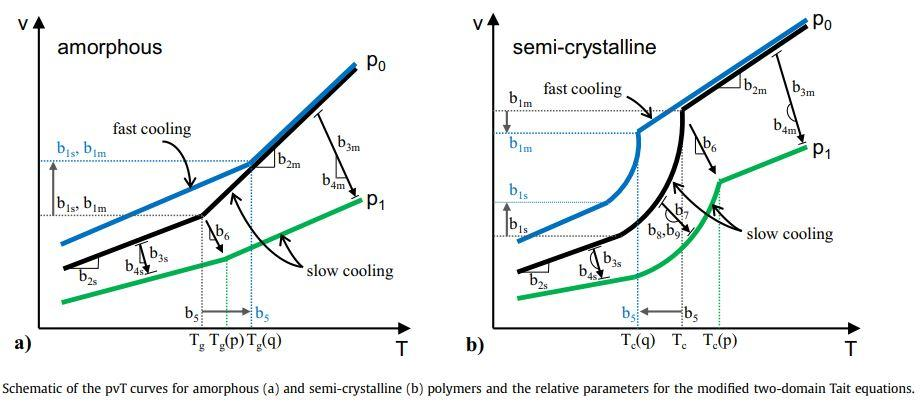

First we obtain b5 and b6, for what we need to know the pressure dependence of Tt:

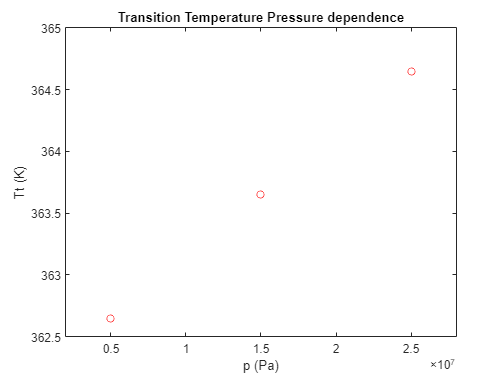

Tt=[362.65 363.65 364.65]; % Re-engineering ;)
p=[0.5 1.5 2.5].*1e07;

figure
plot(p,Tt,'ro')
title('Transition Temperature Pressure dependence')
xlabel('p (Pa)')
ylabel('Tt (K)')
xlim([0.2E07 2.8E07])


Tt=fitlm(p,Tt)

Tt = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE          tStat         pValue  
                   ________    __________    __________    __________

    (Intercept)     362.15     9.2134e-06    3.9307e+07    1.6196e-08
    x1               1e-07     5.3948e-13    1.8536e+05    3.4344e-06


Number of observations: 3, Error degrees of freedom: 1
Root Mean Squared Error: 7.63e-06
R-squared: 1,  Adjusted R-Squared: 1
F-statistic vs. constant model: 1.55e+26, p-value = 5.12e-14

Z = table2struct(Tt.Coefficients(:,1),"ToScalar",true);

% Tt COEFFICIENTS:
b5 = Z.Estimate(1);
b6 = Z.Estimate(2);

### a) Tait MELT (T>Tt) Fitting:

[xData, yData, zData] = prepareSurfaceData( TD_melt, PD_melt, rho_melt );

% Set up fittype and options.
ft = fittype( '(b1m+b2m*(T-362.15-1e-07*p))*(1-0.0894*log(1+p/(b3m*exp(-b4m*(T-362.15-1e-07*p)))))', 'independent', {'T', 'p'}, 'dependent', 'v' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.DiffMinChange = 1e-07;
opts.Display = 'Off';
opts.Robust = 'LAR';
opts.StartPoint = [0.0001 1e-07 100000000 0.001];
opts.DiffMaxChange = 1e-11;
opts.MaxIter = 1e20;
opts.TolX = 1e-20;
opts.TolFun = 1e-20;

% Fit model to data.
[fitresult, gof] = fit( [xData, yData], zData, ft, opts )

     General model:
     fitresult(T,p) = (b1m+b2m*(T-362.15-1e-07*p))*(1-0.0894*log(1+p/(b3m*exp(-
                    b4m*(T-362.15-1e-07*p)))))
     Coefficients (with 95% confidence bounds):
       b1m =    0.000991  (0.0009879, 0.0009941)
       b2m =   7.629e-07  (7.302e-07, 7.955e-07)
       b3m =       1e+08  (7.791e+07, 1.221e+08)
       b4m =     0.00494  (0.003042, 0.006838)



gof = struct with fields:
           sse: 1.1254e-10
       rsquare: 0.9970
           dfe: 25
    adjrsquare: 0.9966
          rmse: 2.1217e-06


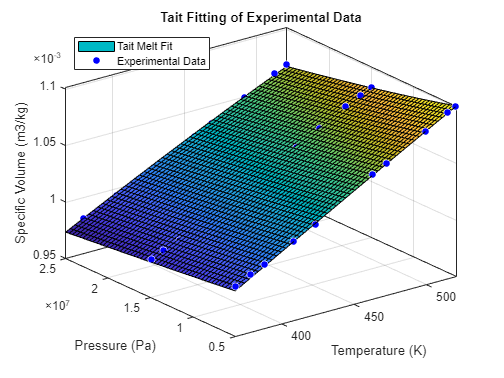

% MELT COEFFICIENTS:
b1m = fitresult.b1m;
b2m = fitresult.b2m;
b3m = fitresult.b3m;
b4m = fitresult.b4m;

% Create a figure for the plots.
figure( 'Name', 'Tait Melt Fitting' );

% Plot fit with data.
h = plot( fitresult, [xData, yData], zData );
legend( h, 'Tait Melt Fit', 'Experimental Data', 'Location', 'NorthWest');
title('Tait Fitting of Experimental Data');
xlabel( 'Temperature (K)');
ylabel( 'Pressure (Pa)');
zlabel( 'Specific Volume (m3/kg)');
grid on

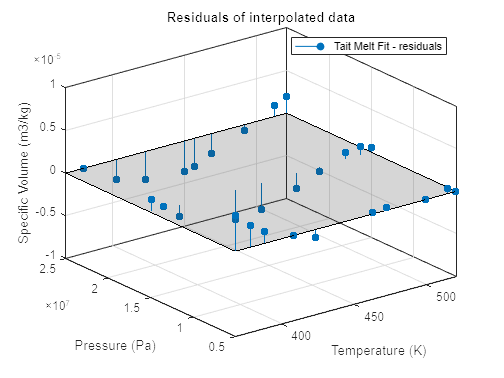

% Plot residuals.
h = plot( fitresult, [xData, yData], zData, 'Style', 'Residual' );
legend( h, 'Tait Melt Fit - residuals', 'Location', 'NorthEast');
title('Residuals of interpolated data');
xlabel( 'Temperature (K)');
ylabel( 'Pressure (Pa)');
zlabel( 'Specific Volume (m3/kg)');
grid on

### b) Tait SOLID (T<Tt) Fitting:

[xData, yData, zData] = prepareSurfaceData( TD_solid, PD_solid, rho_solid);

% Set up fittype and options.
ft = fittype( '(b1s+b2s*(T-362.15-1e-07*p))*(1-0.0894*log(1+p/(b3s*exp(-b4s*(T-362.15-1e-07*p)))))', 'independent', {'T', 'p'}, 'dependent', 'v' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Final';
opts.Robust = 'LAR';
opts.StartPoint = [0.00002 3e-07 9e07 0.001];
opts.DiffMaxChange = 1e-11;
opts.MaxIter = 1e20;
opts.TolX = 1e-20;
opts.TolFun = 1e-20;

% Fit model to data.
[fitresult, gof] = fit( [xData, yData], zData, ft, opts )

Success, but fitting stopped because change in residuals less than tolerance (TolFun).

     General model:
     fitresult(T,p) = (b1s+b2s*(T-362.15-1e-07*p))*(1-0.0894*log(1+p/(b3s*exp(-
                    b4s*(T-362.15-1e-07*p)))))
     Coefficients (with 95% confidence bounds):
       b1s =   0.0009969  (0.0009947, 0.0009991)
       b2s =   3.791e-07  (3.077e-07, 4.506e-07)
       b3s =       9e+07  (7.5e+07, 1.05e+08)
       b4s =    0.004677  (-0.0008272, 0.01018)



gof = struct with fields:
           sse: 9.1044e-12
       rsquare: 0.9923
           dfe: 12
    adjrsquare: 0.9904
          rmse: 8.7104e-07


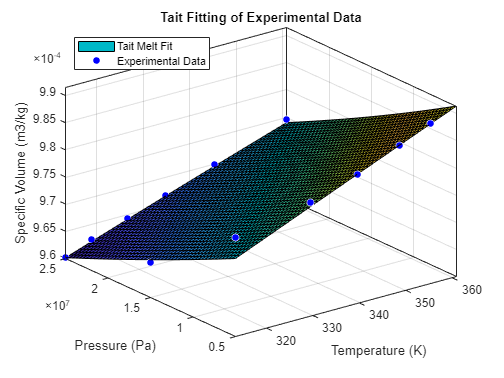

% SOLID COEFFICIENTS:
b1s = fitresult.b1s;
b2s = fitresult.b2s;
b3s = fitresult.b3s;
b4s = fitresult.b4s;

% Create a figure for the plots.
figure( 'Name', 'Tait Melt Fitting' );

% Plot fit with data.
h = plot( fitresult, [xData, yData], zData );
legend( h, 'Tait Melt Fit', 'Experimental Data', 'Location', 'NorthWest');
title('Tait Fitting of Experimental Data');
xlabel( 'Temperature (K)');
ylabel( 'Pressure (Pa)');
zlabel( 'Specific Volume (m3/kg)');
grid on

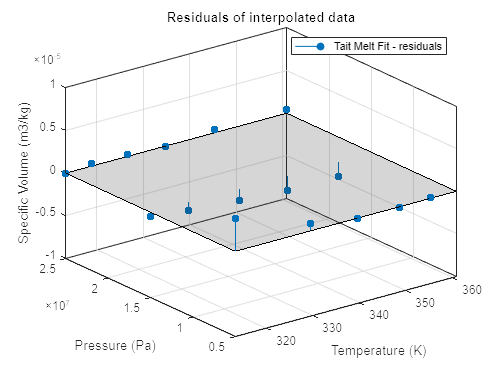

% Plot residuals.
h = plot( fitresult, [xData, yData], zData, 'Style', 'Residual' );
legend( h, 'Tait Melt Fit - residuals', 'Location', 'NorthEast');
title('Residuals of interpolated data');
xlabel( 'Temperature (K)');
ylabel( 'Pressure (Pa)');
zlabel( 'Specific Volume (m3/kg)');
grid on

## **Test: Specific Volume at 50, 150 and 250 bar.**

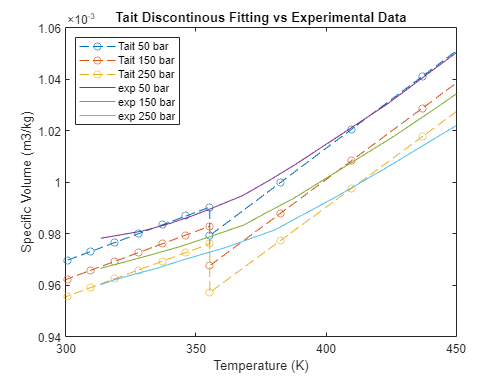

T_solid = linspace(273.15,355.3,10);
T_melt = linspace(355.3,600,10);
T = [T_solid T_melt];

% 50 bar
p50 = 50e05*ones(1,10);

v_solid50 = (b1s+b2s*(T_solid-362.15-1e-07*p50))*(1-0.0894*log(1+p50/(b3s*exp(-b4s*(T_solid-362.15-1e-07*p50)))));
v_melt50 = (0.000991+7.629e-07*(T_melt-362.15-1e-07*p50))*(1-0.0894*log(1+p50/(1e08*exp(-0.00494*(T_melt-362.15-1e-07*p50)))));
v50 = [v_solid50 v_melt50];

plot(T,v50,'--o')
hold on

% 150 bar
p150 = 150e05*ones(1,10);

v_solid150 = (b1s+b2s*(T_solid-362.15-1e-07*p150))*(1-0.0894*log(1+p150/(b3s*exp(-b4s*(T_solid-362.15-1e-07*p150)))));
v_melt150 = (0.000991+7.629e-07*(T_melt-362.15-1e-07*p150))*(1-0.0894*log(1+p150/(1e08*exp(-0.00494*(T_melt-362.15-1e-07*p150)))));
v150 = [v_solid150 v_melt150];

plot(T,v150,'--o')
hold on

% 250 bar
p250 = 250e05*ones(1,10);

v_solid250 = (b1s+b2s*(T_solid-362.15-1e-07*p250))*(1-0.0894*log(1+p250/(b3s*exp(-b4s*(T_solid-362.15-1e-07*p250)))));
v_melt250 = (0.000991+7.629e-07*(T_melt-362.15-1e-07*p250))*(1-0.0894*log(1+p250/(1e08*exp(-0.00494*(T_melt-362.15-1e-07*p250)))));
v250 = [v_solid250 v_melt250];

plot(T,v250,'--o')
hold on

% Experimental data 50 bar
TD_exp50 = [TD1_solid TD1_melt];
rho_exp50 = [rho1_solid rho1_melt]*1e-06;
plot(TD_exp50, rho_exp50)
hold on

% Experimental data 150 bar
TD_exp150 = [TD2_solid TD2_melt];
rho_exp150 = [rho2_solid rho2_melt]*1e-06;
plot(TD_exp150, rho_exp150)
hold on

% Experimental data 250 bar
TD_exp250 = [TD3_solid TD3_melt];
rho_exp250 = [rho3_solid rho3_melt]*1e-06;
plot(TD_exp250, rho_exp250)
hold off

legend('Location', 'NorthWest')

xlim([300 450]);
legend({'Tait 50 bar','Tait 150 bar','Tait 250 bar','exp 50 bar','exp 150 bar','exp 250 bar'}, 'Location', 'NorthWest')
title('Tait Discontinous Fitting vs Experimental Data')
xlabel('Temperature (K)')
ylabel('Specific Volume (m3/kg)')